# File Name: Segmentation_02_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

Create organized synthetic lidar data containing two objects.

ldr = zeros(5,100);
ldr(:,1:50) = 10;
ldr(:,51:end) = 20;
pitch = linspace(-18,18,5);
pitch = repmat(pitch',1,100);
yaw = linspace(-90,90,100);
yaw = repmat(yaw,5,1);

Convert to Cartesian coordinates.

X = ldr .* cosd(pitch) .* sind(yaw);
Y = ldr .* cosd(pitch) .* cosd(yaw);
Z = ldr .* sind(pitch);
ptCloud = pointCloud(cat(3,X,Y,Z));

Plot the results.

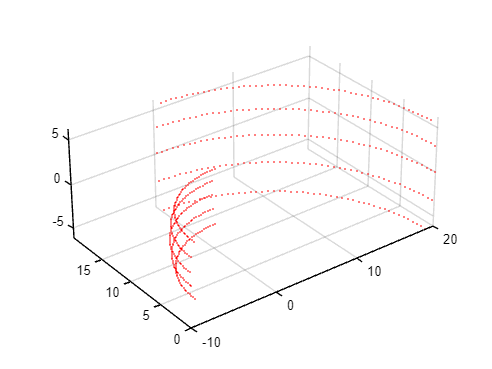

figure
pcshow(ptCloud.Location,'r')
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

Set the threshold.

distThreshold = 5;

%%%%%%%%%% TODO %%%%%%%%%%
% Segment the lidar data.
labels = segmentLidarData(ptCloud,distThreshold);

Plot the results.

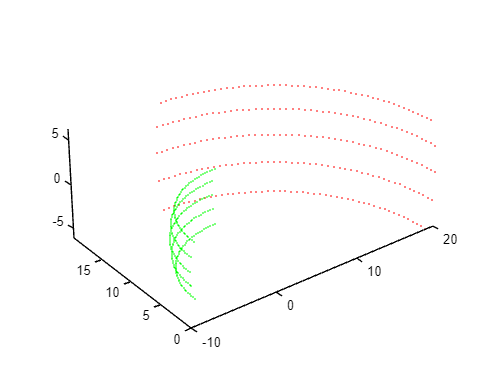

figure
hold on

SegmentedPcLabel1 = select(ptCloud,find(labels == 1));
pcshow(SegmentedPcLabel1.Location,'g')

SegmentedPcLabel2 = select(ptCloud,find(labels == 2));
pcshow(SegmentedPcLabel2.Location,'r')

set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])